syms u(t) v(t)

f =@(t,u,v) v;
g =@(t,u,v) -sin(u)-0.3*v;
a = 0;
b = 15;
n = 100;
u0 = pi/2;
v0 = 0;

SED = [diff(u,t)==f(t,u,v),diff(v,t)==g(t,u,v)];
ci  = [u(a)==u0,v(a)==v0];
[uExata,~] = dsolve(SED,ci);

h =@(t) eval(vectorize(char(uExata)));

[t,u,v] = NEulerSED(f,g,a,b,n,u0,v0)

t =          0    0.1500    0.3000    0.4500    0.6000    0.7500    0.9000    1.0500    1.2000    1.3500    1.5000    1.6500    1.8000    1.9500    2.1000    2.2500    2.4000    2.5500    2.7000    2.8500    3.0000    3.1500    3.3000    3.4500    3.6000    3.7500    3.9000    4.0500    4.2000    4.3500    4.5000    4.6500    4.8000    4.9500    5.1000    5.2500    5.4000    5.5500    5.7000    5.8500    6.0000    6.1500    6.3000    6.4500    6.6000    6.7500    6.9000    7.0500    7.2000    7.3500


u =     1.5708    1.5708    1.5483    1.5043    1.4398    1.3558    1.2532    1.1332    0.9973    0.8471    0.6848    0.5129    0.3346    0.1532   -0.0275   -0.2034   -0.3708   -0.5261   -0.6662   -0.7888   -0.8920   -0.9745   -1.0358   -1.0757   -1.0945   -1.0927   -1.0709   -1.0301   -0.9714   -0.8961   -0.8056   -0.7016   -0.5860   -0.4611   -0.3294   -0.1936   -0.0567    0.0785    0.2088    0.3315    0.4440    0.5441    0.6301    0.7005    0.7545    0.7916    0.8116    0.8147    0.8013    0.7722


v =          0   -0.1500   -0.2933   -0.4300   -0.5603   -0.6838   -0.7996   -0.9061   -1.0012   -1.0822   -1.1459   -1.1892   -1.2093   -1.2041   -1.1728   -1.1159   -1.0354   -0.9345   -0.8171   -0.6876   -0.5502   -0.4087   -0.2662   -0.1252    0.0124    0.1452    0.2718    0.3912    0.5022    0.6035    0.6934    0.7704    0.8326    0.8781    0.9053    0.9131    0.9008    0.8688    0.8179    0.7500    0.6675    0.5730    0.4696    0.3601    0.2472    0.1333    0.0206   -0.0891   -0.1943   -0.2933



array2table([t.',u.',v.'],"VariableNames",{'t','u','v'})

ans = 101×3 table
     t          u           v    
    ____    _________    ________

       0       1.5708           0
    0.15       1.5708       -0.15
     0.3       1.5483    -0.29325
    0.45       1.5043    -0.43002
     0.6       1.4398    -0.56033
    0.75       1.3558    -0.68383
     0.9       1.2532    -0.79961
    1.05       1.1332    -0.90612
     1.2      0.99732     -1.0012
    1.35      0.84714     -1.0822
     1.5      0.68482     -1.1459
    1.65      0.51293     -1.1892
     1.8      0.33456     -1.2093
    1.95      0.15316     -1.2041
     2.1    -0.027455     -1.1728
    2.25     -0.20338     -1.1159


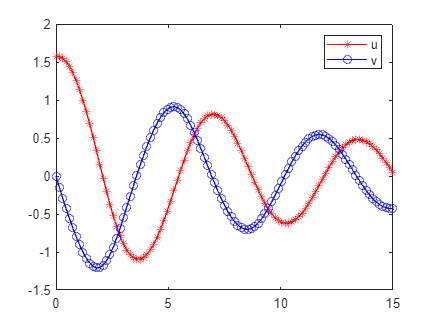


uExata = h(t);


plot(t,u,"-r*")
hold on
plot(t,v,"-bo")
hold off
legend("u","v")

function [t,u,v] = NEulerSED(f,g,a,b,n,u0,v0)
%NEULERSED Método de Euler para um Sistema de SED/PVI
%   Detailed explanation goes here
%   10/04/2024  Arménio Correia   armenioc@isec.pt

h = (b-a)/n;
t = a:h:b;
u = zeros(1,n+1);
v = zeros(1,n+1);
u(1) = u0;
v(1) = v0;
for i = 1:n
    u(i+1) = u(i)+h*f(t(i),u(i),v(i));
    v(i+1) = v(i)+h*g(t(i),u(i),v(i));
end
end